close all, clear all
alpha = 0.05;
dx = 0.05;
dt = 0.075;

k = 74; % thermal conductivity of iron [W/mK]
k = k * 0.25;
cp = 0.45; % specific heat
rho = 7800; % kg/m^3

alpha = k / (cp * rho);  % thermal diffusivity
Fo = alpha * dt / dx^2; % Fourier number
By = dt / (cp*rho*dx^2) * 100;  % defines the power of inputs

loss = 0.001; % loss coefficient [J * K^-1 * s^-1]
Co = loss * (cp/rho) * (dt / dx^2); % "environmental heat loss"

Set up model

side_elements = 20; % number of elements on each side
n_elements = side_elements^2;
% Create a general 2D-plate heat transfer model
[sys, mats] = create_model_fnum(side_elements, Fo, Co, By);  

Creating model
/home/christoph/Projects/MATLABProjects/HeatControl
Model already exists, loading model from models/heatPlateN_12_Fo0-15812_Co1-7308e-06_By0-8547.mat.


T_forward = sys;  % Input T_k, u, output T_k+1

Function to reshape vector to an image array

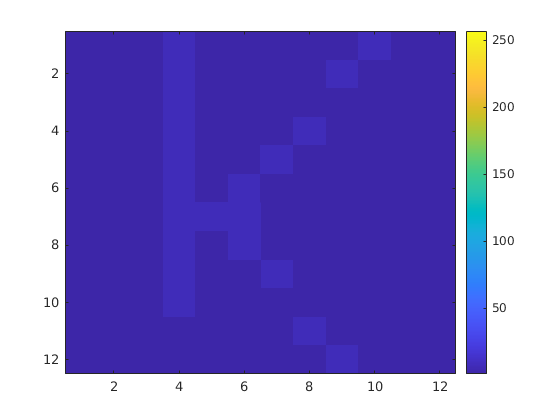

reshape_T = @(T) (reshape(T, [side_elements, side_elements]));
% Reshape image array back to a vector
reshape_T_back = @(Tk) reshape(Tk, [n_elements, 1]);

% Vector of initial node temperatures
img = imread('k_small.png');
img = rgb2gray(img);
img = imresize(img, [side_elements, side_elements]);
img = flip(img);
img = 255-img;
img = img./255;
img = double(img);

% Set reference
W = img * 7;

figure();image(W);colorbar();


T = reshape_T_back(img .* 0);
% T = T + 20;
U = reshape_T_back(img .* 0);
W = reshape_T_back(W);
U_full = U;

## Define control parameters

A = mats.A;  % matrix of system dynamics
B = mats.B;  % external forcing matrix
N = 50; % prediction horizon


The full model assumes that every discrete node has its own input. Reduce the number of inputs used by the control law by creating a new $B$ matrix, which consists of only chosen columns of the original $B$ matrix.

% active_inputs = 1:3:n_elements;  % every third node has an active input
% B = B(:, active_inputs);
% U = U(active_inputs);

% choose input nodes randomly
n_inputs = n_elements//3;  
active_inputs = datasample(1:n_elements, n_inputs, 'Replace', false);
B = B(:, active_inputs);
U = U(active_inputs);

For the purpose of optimizing over the control signal, we must first express the state trajectory


$$\mathbf{x}  = \pmatrix{x_1 \cr x_2 \cr \vdots \cr x_N}$$
 

where N is the prediction horizon, using only the control sequence


$$\mathbf{u}  = \pmatrix{u_0 \cr u_1 \cr \vdots \cr u_{N-1}}$$


and the initial state $x_0$

Create a matrix $\bar{C}$ for particular solution calculation


$$\bar{C} = 
\pmatrix{
B & 0 & \dots & 0 \cr
AB & B & \dots & 0 \cr
\vdots & \ddots & \ddots & \vdots \cr
A^{N-1}B & A^{N-2}B & \dots & B}
$$


The particular solution then has the form


$$\mathbf{x}_p = \bar{C}\mathbf{u}$$


where 

$\mathbf{x}_p = \pmatrix{ x_{1p} \cr x_{2p} \cr \vdots \cr x_{Np}}$ and $\mathbf{u} = \pmatrix{u_0 \cr u_1 \cr \vdots \cr u_{N-1}}$

[blockrows, blockcols] = size(B);
Cbar = sparse(blockrows*N, blockcols*N);
for i = 1:N
    Cbar = Cbar + spblockdiag(A^i * B, N, -1);
end

Similarly, create a matrix for homogeneous solution calculation


$$\hat{A} = \pmatrix{A \cr A^2 \cr \vdots \cr A^N}$$


the homogeneous solution is then


$$\mathbf{x}_h = \hat{A} {x}_0$$


where $x_0$ is the initial state

Ahat = [];
a = A;
for i = 1:N
    Ahat = [Ahat; A^i];
end

The state trajectory in time is then given by 


$$\mathbf{x} = \mathbf{x}_p(\mathbf{u}) + \mathbf{x}_h(x_0)$$


The cost function J is defined as

$J = \frac{1}{2} x_N^TQx_N + \frac{1}{2} \sum_{k=0}^{N-1} (x_k^TQx_k + u_k^TRu_k)$.

The function must be minimized with respect to the control sequence $\mathbf{u}$ and the state trajectory $\mathbf{x}$, subject to the system dynamics given by


$$x_{k+1} = Ax_k + Bu_k$$


and a given initial state $x_0$.

First, define the state error cost matrix $Q$ as an identity matrix, and $\bar{Q}$ as


$$\bar{Q} = \pmatrix{Q & 0 & \dots & 0 \cr
0 & Q & \dots & 0 \cr
0 & 0 & \ddots & 0 \cr
0 & 0 & \dots & Q}$$


similarly, create the matrix $\bar{R}
$ from the control cost matrix ${R}$.

The R and Q weights are chosen as identical. The control can be made less aggresive by increasing the R weights relative to Q, or vice versa.

Q = spdiag(blockrows, 0) * 1;
Qbar = spblockdiag(Q, N, 0);
R = Q * 1;
R = R(active_inputs, active_inputs);
Rbar = spblockdiag(R, N, 0);

With the matrices $\bar{C}, \hat{A}, \bar{Q}, \bar{R}$, it is possible to rewrite the cost function J as

$J = \frac{1}{2}(\bar{C}\mathbf{u}+\hat{A}x_0)^T \bar{Q}(\bar{C}\mathbf{u}+\hat{A}x_0) + \frac{1}{2} \mathbf{u}^T\bar{R}\mathbf{u} + \frac{1}{2} x_0 Q x_0$.

This can be simplified into the standard quadratic form


$$J = \frac{1}{2} \mathbf{u}^T H \mathbf{u} + x_0^T F^T \mathbf{u}$$


where

$H = \bar{C}^T \bar{Q} \bar{C} + R$ and $F^T = \hat{A}^T \bar{Q} \bar{C}$.

The matrices H and F can be used to calculate the control sequence $\mathbf{u}$.

If the control is bounded, H, F and $x_0
$ is used with quadprog to calculate an optimal control sequence.

If the control is not bounded, we can calculate the control sequence by setting the gradient $\nabla_\mathbf{u}J =0$

The gradient of J with respect to the control sequence is


$$\nabla_\mathbf{u}J = H\mathbf{u} + Fx_0$$
 

The control sequence can be computed like this

$\nabla_\mathbf{u}J = H\mathbf{u} + Fx_0 = 0$  $\Rightarrow$ $\mathbf{u} = -H^{-1}Fx_0$ or using the MATLAB backslash operator $\mathbf{u} = -H\backslash Fx_0$

H = (Cbar' * Qbar * Cbar + Rbar);
F = (Ahat' * Qbar * Cbar)';

% Quadprog parameters
Uhat = repmat(U, N, 1);  % initial guess, full control sequence (not actually used for computations)

lb = Uhat.*0 + 0;
ub = Uhat.*0 + 10;

options = optimoptions(@quadprog, 'Algorithm', 'interior-point-convex', ...
    'Display', 'off'); 

The IPC algorithm doesn't accept an initial guess. Other algorithms cannot be used, because they're not implemented to handle sparse matrices, which are necessary due to the size of the system. Full matrices cannot be used for memory (RAM) reasons and because the calculations would be way too slow (most calculations would be multiplying 0s).

## Simulate

stamp = string(round(rand()*10000));
% stamp = 'quadprogMPC_lb0';
savename = "results" + filesep + string(side_elements) + "_" + stamp;

if isfile(savename + '.mat')
    disp("Loading solution for stamp: " + stamp)
    file = load(savename);
    simdata = file.simdata;
else
    disp("Calculating solution for stamp: " + stamp)
    simdata.T = {};
    simdata.T{end+1} = T;
    simdata.U = {};
    simdata.U{end+1} = U_full;
    simdata.E = {};
    simdata.E{end+1} = W-T;
    
    Tk = T;
    k_steps = 500;
    
    for k = 1:k_steps
        
       % State deviation from reference 
       E = W - Tk;
       
       tic
       
%      MPC unconstrained
       f = -(F*E);
       Uhat = -H\f;

       % MPC Quadprog
%        f = -(F*E);
%        Uhat = quadprog(H, f,...
%            [], [],...
%            [], [],...
%            lb, ub,...
%            Uhat, options);
%        
       toc

       U = Uhat(1:blockcols);
       U_full(active_inputs) = U;
       
       % time step forward
       Tk = T_forward(Tk, U_full);
       
%        if k==80
%            disp(k)
%            Tk = reshape_T(Tk);
%            T_diag = spdiag(side_elements, -1) + spdiag(side_elements, 0) +...
%                spdiag(side_elements, 1);
%            T_diag = full(T_diag);
%            T_diag = ones(size(T_diag)) - T_diag;
%            Tk = Tk .* T_diag;
%            Tk = reshape_T_back(Tk);
%        end
%        
       if round(rand*1) == 1
           disp('pop')
            Tk = reshape_T(Tk);
            mid = round(side_elements/2);
            i = mid + rand()*(side_elements - mid) * 0.8;
            j = mid + rand()*(side_elements - mid) * 0.8;
            i = round(i);
            j = round(j);
%             i = (-1:1) + i;
%             j = (-1:1) + j;
            Tk(i,j) = Tk(i,j) - 3;
            Tk = reshape_T_back(Tk);            
       end
       
       % Save current step
       if mod(k,1)==0
        simdata.T{end+1} = Tk;
        simdata.U{end+1} = U_full;
        simdata.E{end+1} = E;
       end
       
       maxabs = max(abs(Tk));
       disp([k, maxabs])

       if maxabs>1e6
           error('Model unstable')
       end
       
    end
    save(savename, 'simdata')
end

Calculating solution for stamp: 9760


Elapsed time is 0.006532 seconds.


    1.0000    1.2090



Elapsed time is 0.003874 seconds.


    2.0000    1.6995



Elapsed time is 0.004916 seconds.


pop


    3.0000    2.9301



Elapsed time is 0.004415 seconds.


    4.0000    2.1331



Elapsed time is 0.004342 seconds.


pop


    5.0000    3.7629



Elapsed time is 0.003717 seconds.


pop


    6.0000    3.2992



Elapsed time is 0.003770 seconds.


pop


    7.0000    3.1059



Elapsed time is 0.003726 seconds.


pop


    8.0000    3.2196



Elapsed time is 0.004604 seconds.


    9.0000    2.5013



Elapsed time is 0.004196 seconds.


pop


   10.0000    4.0848



Elapsed time is 0.003802 seconds.


pop


   11.0000    2.5918



Elapsed time is 0.003821 seconds.


   12.0000    2.5988



Elapsed time is 0.003810 seconds.


pop


   13.0000    3.0284



Elapsed time is 0.003484 seconds.


pop


   14.0000    3.4205



Elapsed time is 0.004016 seconds.


   15.0000    2.6181



Elapsed time is 0.005064 seconds.


   16.0000    2.6441



Elapsed time is 0.003980 seconds.


pop


   17.0000    2.7238



Elapsed time is 0.003667 seconds.


   18.0000    2.6767



Elapsed time is 0.003672 seconds.


   19.0000    2.6899



Elapsed time is 0.003774 seconds.


pop


   20.0000    3.2396



Elapsed time is 0.003723 seconds.


pop


   21.0000    3.3192



Elapsed time is 0.003497 seconds.


pop


   22.0000    2.7571



Elapsed time is 0.005029 seconds.


   23.0000    2.7404



Elapsed time is 0.005129 seconds.


pop


   24.0000    2.8644



Elapsed time is 0.003975 seconds.


   25.0000    2.7638



Elapsed time is 0.003955 seconds.


pop


   26.0000    3.5684



Elapsed time is 0.003715 seconds.


pop


   27.0000    2.8473



Elapsed time is 0.003688 seconds.


pop


   28.0000    2.8034



Elapsed time is 0.003703 seconds.


   29.0000    2.8168



Elapsed time is 0.004702 seconds.


pop


   30.0000    4.0715



Elapsed time is 0.004082 seconds.


pop


   31.0000    2.8592



Elapsed time is 0.003844 seconds.


pop


   32.0000    2.9683



Elapsed time is 0.004726 seconds.


pop


   33.0000    4.3785



Elapsed time is 0.003988 seconds.


pop


   34.0000    4.3126



Elapsed time is 0.003939 seconds.


pop


   35.0000    4.9487



Elapsed time is 0.003847 seconds.


   36.0000    2.8615



Elapsed time is 0.004455 seconds.


pop


   37.0000    3.2819



Elapsed time is 0.004550 seconds.


   38.0000    2.8858



Elapsed time is 0.003752 seconds.


   39.0000    2.8997



Elapsed time is 0.003639 seconds.


pop


   40.0000    2.9143



Elapsed time is 0.004034 seconds.


pop


   41.0000    2.9335



Elapsed time is 0.004769 seconds.


   42.0000    2.9156



Elapsed time is 0.003777 seconds.


   43.0000    2.9193



Elapsed time is 0.004205 seconds.


   44.0000    2.9253



Elapsed time is 0.005047 seconds.


   45.0000    2.9415



Elapsed time is 0.003357 seconds.


pop


   46.0000    3.2266



Elapsed time is 0.003754 seconds.


   47.0000    2.9740



Elapsed time is 0.003383 seconds.


   48.0000    2.9828



Elapsed time is 0.003628 seconds.


   49.0000    2.9930



Elapsed time is 0.003830 seconds.


pop


   50.0000    3.0053



Elapsed time is 0.003817 seconds.


   51.0000    2.9846



Elapsed time is 0.003844 seconds.


   52.0000    2.9878



Elapsed time is 0.003764 seconds.


pop


   53.0000    3.2693



Elapsed time is 0.003771 seconds.


pop


   54.0000    3.5590



Elapsed time is 0.003621 seconds.


pop


   55.0000    3.0140



Elapsed time is 0.003794 seconds.


pop


   56.0000    3.0322



Elapsed time is 0.003579 seconds.


pop


   57.0000    3.5017



Elapsed time is 0.004637 seconds.


pop


   58.0000    3.0180



Elapsed time is 0.003488 seconds.


pop


   59.0000    3.0261



Elapsed time is 0.004391 seconds.


   60.0000    3.0013



Elapsed time is 0.004440 seconds.


pop


   61.0000    3.0123



Elapsed time is 0.003420 seconds.


pop


   62.0000    3.4936



Elapsed time is 0.003994 seconds.


pop


   63.0000    3.1938



Elapsed time is 0.003893 seconds.


   64.0000    2.9743



Elapsed time is 0.003655 seconds.


   65.0000    2.9853



Elapsed time is 0.003512 seconds.


pop


   66.0000    2.9984



Elapsed time is 0.003616 seconds.


pop


   67.0000    3.6953



Elapsed time is 0.003972 seconds.


pop


   68.0000    3.3794



Elapsed time is 0.004688 seconds.


   69.0000    3.0334



Elapsed time is 0.004703 seconds.


   70.0000    3.0417



Elapsed time is 0.003735 seconds.


pop


   71.0000    3.8559



Elapsed time is 0.004542 seconds.


   72.0000    3.0597



Elapsed time is 0.003346 seconds.


pop


   73.0000    3.0698



Elapsed time is 0.003521 seconds.


pop


   74.0000    3.2868



Elapsed time is 0.003797 seconds.


pop


   75.0000    3.4704



Elapsed time is 0.003523 seconds.


pop


   76.0000    4.5166



Elapsed time is 0.003948 seconds.


   77.0000    3.0578



Elapsed time is 0.003606 seconds.


   78.0000    3.0579



Elapsed time is 0.003526 seconds.


   79.0000    3.0632



Elapsed time is 0.003499 seconds.


pop


   80.0000    3.0714



Elapsed time is 0.003548 seconds.


   81.0000    3.0476



Elapsed time is 0.003886 seconds.


pop


   82.0000    3.6731



Elapsed time is 0.003551 seconds.


   83.0000    3.0533



Elapsed time is 0.003554 seconds.


   84.0000    3.0681



Elapsed time is 0.003453 seconds.


   85.0000    3.0817



Elapsed time is 0.003624 seconds.


pop


   86.0000    3.0952



Elapsed time is 0.003568 seconds.


pop


   87.0000    3.4658



Elapsed time is 0.003613 seconds.


pop


   88.0000    3.1095



Elapsed time is 0.003555 seconds.


   89.0000    3.1241



Elapsed time is 0.003769 seconds.


   90.0000    3.1363



Elapsed time is 0.003634 seconds.


   91.0000    3.1445



Elapsed time is 0.003491 seconds.


pop


   92.0000    3.1517



Elapsed time is 0.004235 seconds.


   93.0000    3.1361



Elapsed time is 0.004529 seconds.


pop


   94.0000    3.1562



Elapsed time is 0.003981 seconds.


pop


   95.0000    3.1224



Elapsed time is 0.003791 seconds.


   96.0000    3.1233



Elapsed time is 0.003943 seconds.


   97.0000    3.1319



Elapsed time is 0.004465 seconds.


pop


   98.0000    3.5577



Elapsed time is 0.003767 seconds.


   99.0000    3.1440



Elapsed time is 0.003628 seconds.


pop


  100.0000    3.1530



Elapsed time is 0.003482 seconds.


pop


  101.0000    3.8860



Elapsed time is 0.004806 seconds.


pop


  102.0000    3.1630



Elapsed time is 0.005341 seconds.


pop


  103.0000    3.1121



Elapsed time is 0.004055 seconds.


  104.0000    3.0656



Elapsed time is 0.003824 seconds.


pop


  105.0000    4.0319



Elapsed time is 0.004175 seconds.


pop


  106.0000    4.0092



Elapsed time is 0.003663 seconds.


pop


  107.0000    3.3993



Elapsed time is 0.003620 seconds.


  108.0000    3.1240



Elapsed time is 0.004066 seconds.


pop


  109.0000    3.5708



Elapsed time is 0.004977 seconds.


pop


  110.0000    3.7877



Elapsed time is 0.004266 seconds.


pop


  111.0000    4.1068



Elapsed time is 0.003843 seconds.


  112.0000    3.1597



Elapsed time is 0.003478 seconds.


pop


  113.0000    4.5008



Elapsed time is 0.004699 seconds.


pop


  114.0000    3.4760



Elapsed time is 0.003356 seconds.


pop


  115.0000    3.3737



Elapsed time is 0.003508 seconds.


  116.0000    3.1730



Elapsed time is 0.003538 seconds.


  117.0000    3.1717



Elapsed time is 0.003381 seconds.


  118.0000    3.1755



Elapsed time is 0.003462 seconds.


  119.0000    3.1813



Elapsed time is 0.003592 seconds.


  120.0000    3.1856



Elapsed time is 0.003707 seconds.


  121.0000    3.1901



Elapsed time is 0.003547 seconds.


pop


  122.0000    3.1950



Elapsed time is 0.003536 seconds.


  123.0000    3.2030



Elapsed time is 0.003305 seconds.


pop


  124.0000    3.2056



Elapsed time is 0.003638 seconds.


pop


  125.0000    3.1855



Elapsed time is 0.003396 seconds.


pop


  126.0000    3.5570



Elapsed time is 0.003486 seconds.


  127.0000    3.1957



Elapsed time is 0.003818 seconds.


pop


  128.0000    3.1963



Elapsed time is 0.003628 seconds.


  129.0000    3.1731



Elapsed time is 0.003463 seconds.


pop


  130.0000    3.1670



Elapsed time is 0.003678 seconds.


  131.0000    3.1771



Elapsed time is 0.003727 seconds.


pop


  132.0000    3.5141



Elapsed time is 0.003779 seconds.


  133.0000    3.1850



Elapsed time is 0.003863 seconds.


  134.0000    3.1902



Elapsed time is 0.004691 seconds.


  135.0000    3.1956



Elapsed time is 0.003659 seconds.


  136.0000    3.2013



Elapsed time is 0.003963 seconds.


  137.0000    3.2072



Elapsed time is 0.003563 seconds.


  138.0000    3.2135



Elapsed time is 0.003637 seconds.


pop


  139.0000    3.4616



Elapsed time is 0.003536 seconds.


pop


  140.0000    3.4533



Elapsed time is 0.003932 seconds.


  141.0000    3.2351



Elapsed time is 0.003547 seconds.


  142.0000    3.2419



Elapsed time is 0.004291 seconds.


pop


  143.0000    3.5035



Elapsed time is 0.004189 seconds.


  144.0000    3.2552



Elapsed time is 0.004260 seconds.


  145.0000    3.2622



Elapsed time is 0.003937 seconds.


pop


  146.0000    3.7245



Elapsed time is 0.003545 seconds.


pop


  147.0000    3.2792



Elapsed time is 0.003431 seconds.


  148.0000    3.2851



Elapsed time is 0.003448 seconds.


  149.0000    3.2883



Elapsed time is 0.003935 seconds.


  150.0000    3.2909



Elapsed time is 0.003648 seconds.


  151.0000    3.2934



Elapsed time is 0.003505 seconds.


pop


  152.0000    3.2965



Elapsed time is 0.003546 seconds.


  153.0000    3.2938



Elapsed time is 0.003581 seconds.


pop


  154.0000    3.2921



Elapsed time is 0.003640 seconds.


pop


  155.0000    3.4186



Elapsed time is 0.003457 seconds.


  156.0000    3.1845



Elapsed time is 0.003653 seconds.


  157.0000    3.2054



Elapsed time is 0.003530 seconds.


pop


  158.0000    3.2204



Elapsed time is 0.003543 seconds.


pop


  159.0000    3.2377



Elapsed time is 0.003467 seconds.


pop


  160.0000    3.8052



Elapsed time is 0.003759 seconds.


pop


  161.0000    3.3132



Elapsed time is 0.003872 seconds.


  162.0000    3.2455



Elapsed time is 0.003876 seconds.


pop


  163.0000    3.2494



Elapsed time is 0.003472 seconds.


pop


  164.0000    3.2472



Elapsed time is 0.003706 seconds.


pop


  165.0000    3.3884



Elapsed time is 0.003447 seconds.


pop


  166.0000    3.2566



Elapsed time is 0.003883 seconds.


pop


  167.0000    3.6251



Elapsed time is 0.003608 seconds.


pop


  168.0000    3.2346



Elapsed time is 0.003601 seconds.


  169.0000    3.2353



Elapsed time is 0.003609 seconds.


pop


  170.0000    3.8932



Elapsed time is 0.003490 seconds.


  171.0000    3.2344



Elapsed time is 0.003527 seconds.


pop


  172.0000    3.4383



Elapsed time is 0.003854 seconds.


pop


  173.0000    3.2455



Elapsed time is 0.003922 seconds.


  174.0000    3.2452



Elapsed time is 0.003847 seconds.


pop


  175.0000    3.3306



Elapsed time is 0.004325 seconds.


pop


  176.0000    3.2374



Elapsed time is 0.003921 seconds.


pop


  177.0000    3.2399



Elapsed time is 0.003711 seconds.


pop


  178.0000    3.4099



Elapsed time is 0.004613 seconds.


pop


  179.0000    3.2105



Elapsed time is 0.003912 seconds.


  180.0000    3.1667



Elapsed time is 0.003531 seconds.


  181.0000    3.1762



Elapsed time is 0.003719 seconds.


  182.0000    3.1627



Elapsed time is 0.004586 seconds.


  183.0000    3.1640



Elapsed time is 0.004117 seconds.


  184.0000    3.1685



Elapsed time is 0.003528 seconds.


  185.0000    3.1757



Elapsed time is 0.003500 seconds.


  186.0000    3.1839



Elapsed time is 0.003749 seconds.


pop


  187.0000    3.7795



Elapsed time is 0.003955 seconds.


  188.0000    3.2055



Elapsed time is 0.003611 seconds.


  189.0000    3.2126



Elapsed time is 0.003627 seconds.


  190.0000    3.2184



Elapsed time is 0.003787 seconds.


  191.0000    3.2244



Elapsed time is 0.004544 seconds.


pop


  192.0000    3.8100



Elapsed time is 0.005523 seconds.


pop


  193.0000    3.2421



Elapsed time is 0.004280 seconds.


pop


  194.0000    3.2494



Elapsed time is 0.003720 seconds.


pop


  195.0000    3.2561



Elapsed time is 0.003668 seconds.


pop


  196.0000    3.2371



Elapsed time is 0.003637 seconds.


pop


  197.0000    3.2368



Elapsed time is 0.003568 seconds.


  198.0000    3.2436



Elapsed time is 0.003960 seconds.


  199.0000    3.2386



Elapsed time is 0.003329 seconds.


  200.0000    3.2375



Elapsed time is 0.003544 seconds.


  201.0000    3.2396



Elapsed time is 0.003410 seconds.


  202.0000    3.2432



Elapsed time is 0.004412 seconds.


pop


  203.0000    3.4163



Elapsed time is 0.003481 seconds.


  204.0000    3.2536



Elapsed time is 0.003690 seconds.


  205.0000    3.2601



Elapsed time is 0.003338 seconds.


pop


  206.0000    3.2665



Elapsed time is 0.003389 seconds.


pop


  207.0000    3.2741



Elapsed time is 0.003447 seconds.


pop


  208.0000    3.5569



Elapsed time is 0.003479 seconds.


pop


  209.0000    3.2897



Elapsed time is 0.003616 seconds.


pop


  210.0000    3.2964



Elapsed time is 0.003490 seconds.


  211.0000    3.2709



Elapsed time is 0.003573 seconds.


pop


  212.0000    3.2623



Elapsed time is 0.003444 seconds.


pop


  213.0000    3.5019



Elapsed time is 0.003808 seconds.


  214.0000    3.2678



Elapsed time is 0.003378 seconds.


pop


  215.0000    3.2612



Elapsed time is 0.003527 seconds.


  216.0000    3.2534



Elapsed time is 0.003456 seconds.


pop


  217.0000    3.2985



Elapsed time is 0.003729 seconds.


pop


  218.0000    3.9225



Elapsed time is 0.003835 seconds.


pop


  219.0000    3.9456



Elapsed time is 0.003401 seconds.


pop


  220.0000    3.2639



Elapsed time is 0.004499 seconds.


  221.0000    3.2109



Elapsed time is 0.003624 seconds.


pop


  222.0000    3.2972



Elapsed time is 0.003401 seconds.


pop


  223.0000    3.1762



Elapsed time is 0.003850 seconds.


pop


  224.0000    3.1513



Elapsed time is 0.003450 seconds.


pop


  225.0000    3.1895



Elapsed time is 0.003662 seconds.


pop


  226.0000    3.7631



Elapsed time is 0.003554 seconds.


pop


  227.0000    3.3230



Elapsed time is 0.003449 seconds.


  228.0000    3.1575



Elapsed time is 0.003901 seconds.


  229.0000    3.1642



Elapsed time is 0.003556 seconds.


  230.0000    3.1725



Elapsed time is 0.003688 seconds.


pop


  231.0000    3.1810



Elapsed time is 0.003603 seconds.


pop


  232.0000    3.7024



Elapsed time is 0.003905 seconds.


pop


  233.0000    3.1692



Elapsed time is 0.003465 seconds.


pop


  234.0000    3.3258



Elapsed time is 0.004387 seconds.


  235.0000    3.1832



Elapsed time is 0.004069 seconds.


  236.0000    3.1865



Elapsed time is 0.003547 seconds.


pop


  237.0000    3.4115



Elapsed time is 0.003831 seconds.


  238.0000    3.2029



Elapsed time is 0.003626 seconds.


pop


  239.0000    3.2031



Elapsed time is 0.003917 seconds.


  240.0000    3.1493



Elapsed time is 0.003612 seconds.


  241.0000    3.0972



Elapsed time is 0.003693 seconds.


  242.0000    3.1186



Elapsed time is 0.004108 seconds.


  243.0000    3.1357



Elapsed time is 0.004500 seconds.


  244.0000    3.1542



Elapsed time is 0.003396 seconds.


pop


  245.0000    3.1705



Elapsed time is 0.004100 seconds.


pop


  246.0000    3.1626



Elapsed time is 0.003784 seconds.


  247.0000    3.1722



Elapsed time is 0.003651 seconds.


  248.0000    3.1864



Elapsed time is 0.003745 seconds.


  249.0000    3.1945



Elapsed time is 0.004634 seconds.


pop


  250.0000    3.4509



Elapsed time is 0.004236 seconds.


pop


  251.0000    3.6071



Elapsed time is 0.003407 seconds.


pop


  252.0000    3.9275



Elapsed time is 0.003777 seconds.


  253.0000    3.2329



Elapsed time is 0.004499 seconds.


  254.0000    3.2394



Elapsed time is 0.004120 seconds.


  255.0000    3.2454



Elapsed time is 0.003506 seconds.


pop


  256.0000    3.7706



Elapsed time is 0.003966 seconds.


pop


  257.0000    3.4308



Elapsed time is 0.004892 seconds.


pop


  258.0000    3.3031



Elapsed time is 0.003568 seconds.


pop


  259.0000    3.2703



Elapsed time is 0.003709 seconds.


  260.0000    3.2439



Elapsed time is 0.003454 seconds.


pop


  261.0000    3.5424



Elapsed time is 0.003655 seconds.


  262.0000    3.2378



Elapsed time is 0.003860 seconds.


pop


  263.0000    3.2392



Elapsed time is 0.003427 seconds.


pop


  264.0000    3.7398



Elapsed time is 0.003579 seconds.


pop


  265.0000    3.2531



Elapsed time is 0.003515 seconds.


pop


  266.0000    4.0128



Elapsed time is 0.003637 seconds.


  267.0000    3.1468



Elapsed time is 0.004158 seconds.


  268.0000    3.1671



Elapsed time is 0.003752 seconds.


pop


  269.0000    3.6127



Elapsed time is 0.003542 seconds.


pop


  270.0000    3.2351



Elapsed time is 0.003702 seconds.


pop


  271.0000    3.8862



Elapsed time is 0.003425 seconds.


  272.0000    3.2263



Elapsed time is 0.003380 seconds.


pop


  273.0000    3.2355



Elapsed time is 0.003411 seconds.


  274.0000    3.2449



Elapsed time is 0.003462 seconds.


  275.0000    3.2528



Elapsed time is 0.003434 seconds.


pop


  276.0000    3.2593



Elapsed time is 0.003451 seconds.


pop


  277.0000    3.2651



Elapsed time is 0.003450 seconds.


  278.0000    3.2662



Elapsed time is 0.003652 seconds.


  279.0000    3.2650



Elapsed time is 0.003436 seconds.


pop


  280.0000    3.2652



Elapsed time is 0.003453 seconds.


pop


  281.0000    3.3273



Elapsed time is 0.003406 seconds.


  282.0000    3.2738



Elapsed time is 0.003503 seconds.


  283.0000    3.2701



Elapsed time is 0.003650 seconds.


pop


  284.0000    3.3838



Elapsed time is 0.003635 seconds.


pop


  285.0000    4.1713



Elapsed time is 0.003404 seconds.


  286.0000    3.2764



Elapsed time is 0.003628 seconds.


pop


  287.0000    3.2783



Elapsed time is 0.003445 seconds.


pop


  288.0000    3.2232



Elapsed time is 0.003438 seconds.


  289.0000    3.1630



Elapsed time is 0.003702 seconds.


pop


  290.0000    3.4081



Elapsed time is 0.003623 seconds.


  291.0000    3.1829



Elapsed time is 0.003913 seconds.


  292.0000    3.1927



Elapsed time is 0.003347 seconds.


  293.0000    3.2032



Elapsed time is 0.003514 seconds.


  294.0000    3.2147



Elapsed time is 0.003816 seconds.


  295.0000    3.2233



Elapsed time is 0.003293 seconds.


pop


  296.0000    3.2311



Elapsed time is 0.003888 seconds.


pop


  297.0000    3.2142



Elapsed time is 0.003541 seconds.


  298.0000    3.2062



Elapsed time is 0.003662 seconds.


pop


  299.0000    3.4415



Elapsed time is 0.003338 seconds.


pop


  300.0000    3.2123



Elapsed time is 0.004764 seconds.


  301.0000    3.1984



Elapsed time is 0.003535 seconds.


pop


  302.0000    3.2068



Elapsed time is 0.003419 seconds.


pop


  303.0000    3.8408



Elapsed time is 0.003549 seconds.


pop


  304.0000    3.2279



Elapsed time is 0.003936 seconds.


pop


  305.0000    3.4236



Elapsed time is 0.003687 seconds.


  306.0000    3.2257



Elapsed time is 0.003776 seconds.


  307.0000    3.2241



Elapsed time is 0.003816 seconds.


pop


  308.0000    3.3286



Elapsed time is 0.003820 seconds.


pop


  309.0000    3.2313



Elapsed time is 0.004166 seconds.


  310.0000    3.2373



Elapsed time is 0.003637 seconds.


  311.0000    3.2364



Elapsed time is 0.003384 seconds.


  312.0000    3.2358



Elapsed time is 0.003315 seconds.


pop


  313.0000    3.5362



Elapsed time is 0.003410 seconds.


pop


  314.0000    4.2227



Elapsed time is 0.003267 seconds.


pop


  315.0000    3.2505



Elapsed time is 0.003651 seconds.


  316.0000    3.2545



Elapsed time is 0.003498 seconds.


  317.0000    3.2563



Elapsed time is 0.003601 seconds.


pop


  318.0000    3.6196



Elapsed time is 0.003458 seconds.


pop


  319.0000    3.3318



Elapsed time is 0.003466 seconds.


pop


  320.0000    4.0075



Elapsed time is 0.003485 seconds.


pop


  321.0000    3.2517



Elapsed time is 0.003929 seconds.


  322.0000    3.2466



Elapsed time is 0.003565 seconds.


pop


  323.0000    3.2462



Elapsed time is 0.003444 seconds.


  324.0000    3.2492



Elapsed time is 0.003724 seconds.


pop


  325.0000    3.4122



Elapsed time is 0.003727 seconds.


  326.0000    3.2613



Elapsed time is 0.003454 seconds.


  327.0000    3.2650



Elapsed time is 0.003601 seconds.


pop


  328.0000    3.6105



Elapsed time is 0.003769 seconds.


pop


  329.0000    3.2709



Elapsed time is 0.003451 seconds.


  330.0000    3.2519



Elapsed time is 0.003659 seconds.


pop


  331.0000    3.5497



Elapsed time is 0.004213 seconds.


pop


  332.0000    3.5235



Elapsed time is 0.004501 seconds.


  333.0000    3.2562



Elapsed time is 0.004246 seconds.


  334.0000    3.2584



Elapsed time is 0.003954 seconds.


pop


  335.0000    3.2615



Elapsed time is 0.003778 seconds.


  336.0000    3.2697



Elapsed time is 0.003935 seconds.


pop


  337.0000    3.8880



Elapsed time is 0.004024 seconds.


  338.0000    3.2818



Elapsed time is 0.004587 seconds.


  339.0000    3.2834



Elapsed time is 0.003588 seconds.


pop


  340.0000    3.6655



Elapsed time is 0.003604 seconds.


  341.0000    3.2863



Elapsed time is 0.003933 seconds.


pop


  342.0000    3.5303



Elapsed time is 0.003545 seconds.


pop


  343.0000    3.2931



Elapsed time is 0.003565 seconds.


pop


  344.0000    3.6390



Elapsed time is 0.004081 seconds.


  345.0000    3.2909



Elapsed time is 0.003871 seconds.


  346.0000    3.2897



Elapsed time is 0.003564 seconds.


pop


  347.0000    3.5652



Elapsed time is 0.003855 seconds.


pop


  348.0000    3.2881



Elapsed time is 0.004051 seconds.


pop


  349.0000    4.0143



Elapsed time is 0.004677 seconds.


pop


  350.0000    3.5164



Elapsed time is 0.003889 seconds.


  351.0000    3.2712



Elapsed time is 0.004257 seconds.


pop


  352.0000    3.4343



Elapsed time is 0.003832 seconds.


pop


  353.0000    3.3399



Elapsed time is 0.003840 seconds.


  354.0000    3.2649



Elapsed time is 0.004755 seconds.


pop


  355.0000    3.2617



Elapsed time is 0.004351 seconds.


  356.0000    3.2406



Elapsed time is 0.003549 seconds.


pop


  357.0000    3.2429



Elapsed time is 0.003647 seconds.


  358.0000    3.2114



Elapsed time is 0.003586 seconds.


  359.0000    3.2218



Elapsed time is 0.003786 seconds.


pop


  360.0000    3.5875



Elapsed time is 0.003466 seconds.


  361.0000    3.2090



Elapsed time is 0.003498 seconds.


  362.0000    3.2123



Elapsed time is 0.003613 seconds.


pop


  363.0000    3.2169



Elapsed time is 0.003694 seconds.


pop


  364.0000    3.3598



Elapsed time is 0.003508 seconds.


pop


  365.0000    3.1879



Elapsed time is 0.003623 seconds.


  366.0000    3.1835



Elapsed time is 0.004144 seconds.


  367.0000    3.1908



Elapsed time is 0.004054 seconds.


  368.0000    3.1999



Elapsed time is 0.004014 seconds.


  369.0000    3.2092



Elapsed time is 0.003891 seconds.


pop


  370.0000    3.2187



Elapsed time is 0.003657 seconds.


pop


  371.0000    3.3185



Elapsed time is 0.003831 seconds.


  372.0000    3.2263



Elapsed time is 0.004082 seconds.


pop


  373.0000    3.2336



Elapsed time is 0.004197 seconds.


  374.0000    3.2440



Elapsed time is 0.004243 seconds.


  375.0000    3.2508



Elapsed time is 0.003953 seconds.


  376.0000    3.2562



Elapsed time is 0.004027 seconds.


  377.0000    3.2608



Elapsed time is 0.003829 seconds.


pop


  378.0000    3.3724



Elapsed time is 0.003837 seconds.


pop


  379.0000    3.2706



Elapsed time is 0.003513 seconds.


  380.0000    3.2803



Elapsed time is 0.003597 seconds.


  381.0000    3.2859



Elapsed time is 0.003467 seconds.


pop


  382.0000    3.2899



Elapsed time is 0.003516 seconds.


pop


  383.0000    3.7587



Elapsed time is 0.003531 seconds.


  384.0000    3.3043



Elapsed time is 0.003448 seconds.


pop


  385.0000    3.3055



Elapsed time is 0.003698 seconds.


  386.0000    3.2497



Elapsed time is 0.003364 seconds.


pop


  387.0000    3.6196



Elapsed time is 0.003587 seconds.


pop


  388.0000    3.2100



Elapsed time is 0.003557 seconds.


  389.0000    3.2181



Elapsed time is 0.003531 seconds.


pop


  390.0000    3.2244



Elapsed time is 0.003402 seconds.


pop


  391.0000    3.2254



Elapsed time is 0.003590 seconds.


  392.0000    3.1945



Elapsed time is 0.003426 seconds.


  393.0000    3.1919



Elapsed time is 0.003441 seconds.


  394.0000    3.1942



Elapsed time is 0.003514 seconds.


  395.0000    3.2045



Elapsed time is 0.003867 seconds.


  396.0000    3.2144



Elapsed time is 0.003772 seconds.


  397.0000    3.2243



Elapsed time is 0.003709 seconds.


pop


  398.0000    3.2339



Elapsed time is 0.004224 seconds.


  399.0000    3.2473



Elapsed time is 0.004210 seconds.


pop


  400.0000    3.2562



Elapsed time is 0.003885 seconds.


pop


  401.0000    3.3795



Elapsed time is 0.004123 seconds.


  402.0000    3.2403



Elapsed time is 0.004086 seconds.


  403.0000    3.2494



Elapsed time is 0.004399 seconds.


pop


  404.0000    3.2541



Elapsed time is 0.004000 seconds.


pop


  405.0000    3.7547



Elapsed time is 0.004105 seconds.


pop


  406.0000    3.2505



Elapsed time is 0.004033 seconds.


  407.0000    3.2494



Elapsed time is 0.003894 seconds.


  408.0000    3.2557



Elapsed time is 0.004074 seconds.


  409.0000    3.2625



Elapsed time is 0.004164 seconds.


  410.0000    3.2674



Elapsed time is 0.004063 seconds.


pop


  411.0000    3.3761



Elapsed time is 0.004172 seconds.


  412.0000    3.2753



Elapsed time is 0.004084 seconds.


pop


  413.0000    3.2720



Elapsed time is 0.004852 seconds.


  414.0000    3.2726



Elapsed time is 0.004023 seconds.


  415.0000    3.2751



Elapsed time is 0.004145 seconds.


  416.0000    3.2798



Elapsed time is 0.003997 seconds.


pop


  417.0000    3.2850



Elapsed time is 0.004213 seconds.


pop


  418.0000    3.2577



Elapsed time is 0.004016 seconds.


pop


  419.0000    3.2491



Elapsed time is 0.003866 seconds.


  420.0000    3.2449



Elapsed time is 0.005307 seconds.


pop


  421.0000    3.2495



Elapsed time is 0.003876 seconds.


  422.0000    3.2587



Elapsed time is 0.003840 seconds.


pop


  423.0000    3.2619



Elapsed time is 0.004068 seconds.


  424.0000    3.2678



Elapsed time is 0.003986 seconds.


pop


  425.0000    3.2702



Elapsed time is 0.003907 seconds.


  426.0000    3.2726



Elapsed time is 0.003947 seconds.


  427.0000    3.2759



Elapsed time is 0.004030 seconds.


  428.0000    3.2800



Elapsed time is 0.004063 seconds.


pop


  429.0000    3.2842



Elapsed time is 0.003865 seconds.


pop


  430.0000    3.2837



Elapsed time is 0.004072 seconds.


  431.0000    3.2824



Elapsed time is 0.003888 seconds.


  432.0000    3.2862



Elapsed time is 0.004000 seconds.


pop


  433.0000    3.2924



Elapsed time is 0.004027 seconds.


  434.0000    3.2992



Elapsed time is 0.003972 seconds.


pop


  435.0000    3.3170



Elapsed time is 0.004454 seconds.


pop


  436.0000    3.3030



Elapsed time is 0.004314 seconds.


  437.0000    3.2724



Elapsed time is 0.003712 seconds.


pop


  438.0000    3.2653



Elapsed time is 0.003960 seconds.


  439.0000    3.2654



Elapsed time is 0.003972 seconds.


pop


  440.0000    3.2719



Elapsed time is 0.004031 seconds.


  441.0000    3.2781



Elapsed time is 0.004078 seconds.


pop


  442.0000    3.3266



Elapsed time is 0.004094 seconds.


  443.0000    3.2788



Elapsed time is 0.004016 seconds.


  444.0000    3.2832



Elapsed time is 0.004679 seconds.


  445.0000    3.2878



Elapsed time is 0.004474 seconds.


pop


  446.0000    3.2928



Elapsed time is 0.003928 seconds.


  447.0000    3.2751



Elapsed time is 0.003885 seconds.


pop


  448.0000    3.4950



Elapsed time is 0.003769 seconds.


pop


  449.0000    3.5785



Elapsed time is 0.004389 seconds.


  450.0000    3.2876



Elapsed time is 0.004269 seconds.


pop


  451.0000    3.2918



Elapsed time is 0.003991 seconds.


pop


  452.0000    3.6073



Elapsed time is 0.003975 seconds.


  453.0000    3.3017



Elapsed time is 0.003910 seconds.


  454.0000    3.3065



Elapsed time is 0.003882 seconds.


  455.0000    3.3111



Elapsed time is 0.003869 seconds.


  456.0000    3.3155



Elapsed time is 0.003611 seconds.


  457.0000    3.3197



Elapsed time is 0.003925 seconds.


pop


  458.0000    3.3554



Elapsed time is 0.003667 seconds.


  459.0000    3.3269



Elapsed time is 0.003590 seconds.


pop


  460.0000    3.3229



Elapsed time is 0.003802 seconds.


  461.0000    3.3259



Elapsed time is 0.003466 seconds.


pop


  462.0000    3.3266



Elapsed time is 0.003488 seconds.


pop


  463.0000    3.3473



Elapsed time is 0.003416 seconds.


  464.0000    3.3323



Elapsed time is 0.003673 seconds.


pop


  465.0000    4.0797



Elapsed time is 0.003774 seconds.


pop


  466.0000    3.3407



Elapsed time is 0.003514 seconds.


  467.0000    3.3470



Elapsed time is 0.003484 seconds.


  468.0000    3.3483



Elapsed time is 0.003456 seconds.


  469.0000    3.3478



Elapsed time is 0.003549 seconds.


  470.0000    3.3481



Elapsed time is 0.003424 seconds.


  471.0000    3.3495



Elapsed time is 0.003555 seconds.


  472.0000    3.3511



Elapsed time is 0.003910 seconds.


pop


  473.0000    3.3531



Elapsed time is 0.012078 seconds.


pop


  474.0000    3.5996



Elapsed time is 0.004047 seconds.


  475.0000    3.3643



Elapsed time is 0.003778 seconds.


  476.0000    3.3649



Elapsed time is 0.003905 seconds.


pop


  477.0000    3.3639



Elapsed time is 0.004249 seconds.


pop


  478.0000    3.3661



Elapsed time is 0.004254 seconds.


  479.0000    3.3661



Elapsed time is 0.004105 seconds.


  480.0000    3.3607



Elapsed time is 0.003221 seconds.


pop


  481.0000    3.3569



Elapsed time is 0.003372 seconds.


pop


  482.0000    3.3332



Elapsed time is 0.003689 seconds.


  483.0000    3.3282



Elapsed time is 0.003777 seconds.


pop


  484.0000    3.5701



Elapsed time is 0.003423 seconds.


  485.0000    3.3268



Elapsed time is 0.003567 seconds.


  486.0000    3.3203



Elapsed time is 0.003436 seconds.


  487.0000    3.3173



Elapsed time is 0.003939 seconds.


  488.0000    3.3177



Elapsed time is 0.003343 seconds.


pop


  489.0000    3.3192



Elapsed time is 0.003609 seconds.


  490.0000    3.2969



Elapsed time is 0.003513 seconds.


pop


  491.0000    3.3344



Elapsed time is 0.003675 seconds.


  492.0000    3.2842



Elapsed time is 0.003648 seconds.


  493.0000    3.2878



Elapsed time is 0.003368 seconds.


  494.0000    3.2929



Elapsed time is 0.003549 seconds.


pop


  495.0000    3.2997



Elapsed time is 0.003839 seconds.


  496.0000    3.3069



Elapsed time is 0.003449 seconds.


  497.0000    3.3145



Elapsed time is 0.003570 seconds.


pop


  498.0000    3.3398



Elapsed time is 0.003782 seconds.


pop


  499.0000    3.3276



Elapsed time is 0.003796 seconds.


pop


  500.0000    3.3264



## Visualization

Reshape the vector of node temperatures into a 2D array for plotting

Tk = reshape_T(T);

elements = 0:dx:side_elements*dx-dx;
[X, Y] = meshgrid(elements, elements);

f = figure('Position', [0 0 1400 1000]);
set(f, 'Visible', 'on')
t = tiledlayout(2, 3, 'TileSpacing', 'tight', 'Padding', 'tight');


ax1 = nexttile([2,2]);
% splot = surfc(ax1, X, Y, Tk, 'facealpha', 0.85);
[m, splot] = contourf(ax1, X, Y, Tk);
splot.LevelStep = 1;
splot.LevelList = [-5:0.125:10];
splot.LineColor = 'none';
axis equal

hold on
ax1.ZLimMode = 'manual';
ax1.ZLim = [-6 7];   % Z limit is constant
ax1.CLim = [-6 7];  % Colorbar range
colorbar
colormap(jet)
hold off

ax2 = nexttile(3);
yyaxis left
ylabel('Power')
powerplot = animatedline(ax2, 'Marker', 'o', 'linewidth', 2, 'color', 'blue');
yyaxis right
ylabel('Mean square error')
errorplot = animatedline(ax2, 'Marker', 'o', 'linewidth', 2, 'color', [1,0.55,0]);
grid on

ax3 = nexttile(6);
Uk = reshape_T(simdata.U{1});
inputimg = image(ax3, elements', elements', flip(Uk, 1));
inputimg.CDataMapping = 'scaled';
title('Heat input image')
    cmap = [zeros(1,128), linspace(0,1,128);
        linspace(1,0,128), linspace(0,1,128);
        linspace(1,0,128), zeros(1,128)]';
    cmap = (cmap.*0+1) - cmap; %invert
ax3.CLim = [-3, 3];
ax3.Colormap = flip(cmap);
colorbar()

frames = [getframe(f)];
L = length(simdata);

% t = round(linspace(1, length(simdata.T)*dt, 300));
% t = t - t(1) + 1;

t = 1:k_steps;

framenum = 0;
for k = t
    disp(k)
    framenum = framenum + 1;
    
    T = simdata.T{k};
    U = simdata.U{k};
    E = simdata.E{k};
    
    Tk = reshape_T(T);
    Uk = reshape_T(U);
        
%     splot.ZData = Tk;
    splot(1).ZData = Tk;

    addpoints(powerplot, k*dt, norm(U));
    addpoints(errorplot, k*dt, mean(E.^2));
    
    inputimg.CData = flip(Uk, 1);
    
    drawnow
    frames(end+1) = getframe(f);
   
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64




% writerObj = VideoWriter('animation');
% writerObj.FrameRate = 20;
% 
% open(writerObj);
% for k = 2:length(frames)
%    frame = frames(k);
%    writeVideo(writerObj, frame);
% end
% close(writerObj);